# Exercise 3.3 - Reverberation

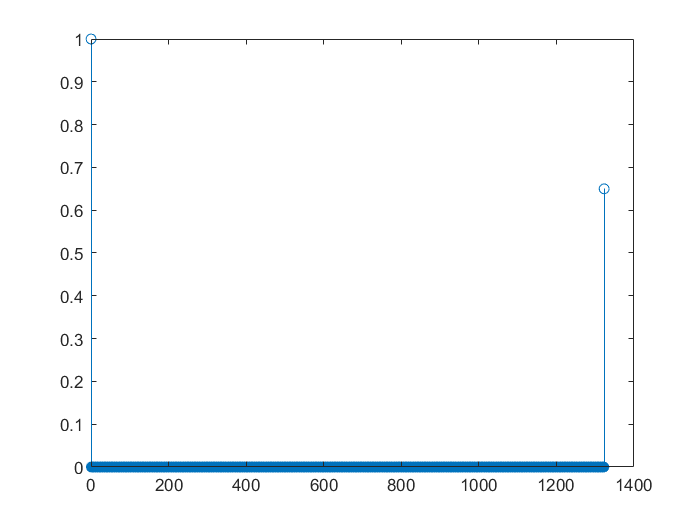

% Import audio file
[kick, fs] = audioread('audio\kick.mp3');
%sound(kick, fs)

% Reverberation setup
rev1 = 8e-3;
rev2 = 30e-3;
numSamples1 = round(fs * rev1);
numSamples2 = round(fs * rev2);
a = zeros(1, numSamples2 + 1);
a(1) = 1;
a(numSamples2 + 1) = 0.65;
b = 1;

% Apply filter and play output signal
y = filter(b, a, kick);
sound(y, fs)

% Export resulting audio fragment in WAV format
audiowrite('audio\output3_3.wav', 0.25 * y, fs);

% Plot the a coefficients vector
n = 0 : numSamples2;
stem(n, a);